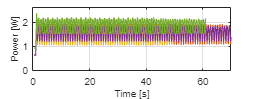

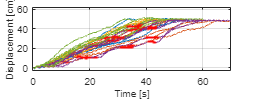

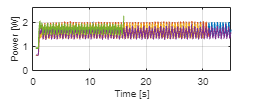

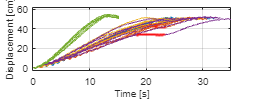

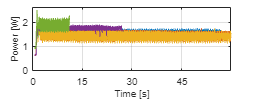

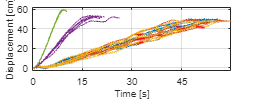

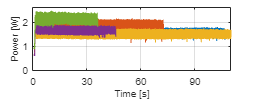

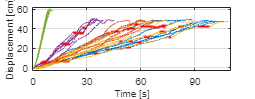

clear; clc; close all;

%% ============================================
%% ROOT FOLDER
%% ============================================

root = 'data/swimming/forward-locomotion';

%% ============================================
%% PARAMETERS
%% ============================================

rho_water = 1000;        % kg/m^3
mu_water  = 0.00089;    % Pa*s
body_length_m = 0.4542;
tail_amplitude_m = 10^-2 * [8.575 8.538 4.956 2.457
                    7.752 7.962 5.312 2.587
                    7.602 7.918 5.293 2.279
                    8.069 8.057 6.028 4.320
                    7.276 8.193 7.643 6.189]; % peak-to-peak

robot_mass_kg = 1.02;   % CHANGE THIS

g = 9.81;

%% ============================================
%% MODES AND FREQUENCIES
%% ============================================

modeType = {'anguilliform'; ...
            'subcarangiform'; ...
            'carangiform'; ...
            'thunniform'; ...
            'ostraciiform'};

mode = {'Anguilliform'; ...
            'Subcarangiform'; ...
            'Carangiform'; ...
            'Thunniform'; ...
            'Ostraciiform'};

frequency = {'0.6Hz'; '1Hz'; '1.5Hz'; '2Hz'};
frequency_num = [0.6 1 1.5 2];

% colors = [0.588, 0.200, 0.902
%           0 0.5 1
%           0 0.5 0
%           0.9290, 0.6940, 0.1250];
colors = lines(5);

%% ============================================
%% ANALYSIS PARAMETERS
%% ============================================

cycles_per_window = 3;
velocity_threshold = 0.35;
min_points = 5;

analysis_min_x = 5;   % cm
analysis_max_x = 45;   % cm

%% ============================================
%% POWER PARAMETERS
%% ============================================

power_smoothing_time = 0.3;   % seconds
power_time_offset = 0.55;

%% ============================================
%% AXIS LIMITS (SET THESE MANUALLY)
%% ============================================

%% Displacement figure limits
disp_xlim = [0 70
             0 35
             0 60
             0 110];
disp_ylim = [-3 62];

disp_xticks = [0 20 40 60
               0 10 20 30
               0 15 30 45
               0 30 60 90];

%% Power figure limits
power_xlim = disp_xlim;
power_ylim = [0 2.6];

power_xticks = disp_xticks;

plotW = 9;
plotH = 3.5;

%% ============================================
%% RESULT TABLE
%% ============================================

Results = table();

%% ============================================
%% MAIN LOOP
%% ============================================

for f = 1:length(frequency_num)

    %% ========================================
    %% CREATE FIGURES
    %% ========================================

    fig_disp = figure( ...
        'Name', [frequency{f} ' displacement']);

    hold on;

    fig_power = figure( ...
        'Name', [frequency{f} ' power']);

    hold on;

    %% ========================================
    %% LOOP FREQUENCIES
    %% ========================================

    for m = 1:length(modeType)

        %% Sliding regression window
        window_time = ...
            cycles_per_window / frequency_num(f);

        %% Folders
        tracking_folder = fullfile( ...
            root, ...
            modeType{m}, ...
            'tracking', ...
            frequency{f});

        power_folder = fullfile( ...
            root, ...
            modeType{m}, ...
            'power', ...
            frequency{f});

        tracking_files = ...
            dir(fullfile(tracking_folder, '*.txt'));

        %% ====================================
        %% LOOP TRIALS
        %% ====================================

        for k = 1:length(tracking_files)

            %% --------------------------------
            %% LOAD TRACKING
            %% --------------------------------

            tracking_path = fullfile( ...
                tracking_folder, ...
                tracking_files(k).name);

            data = readmatrix(tracking_path);

            t = data(:,1);
            x = data(:,2);

            %% Remove NaNs
            good = ~(isnan(t) | isnan(x));

            t = t(good);
            x = x(good);

            %% --------------------------------
            %% ANALYSIS REGION
            %% --------------------------------

            analysis_idx = ...
                (x >= analysis_min_x) & ...
                (x <= analysis_max_x);

            t_analysis = t(analysis_idx);
            x_analysis = x(analysis_idx);

            if length(t_analysis) < 10
                continue;
            end

            %% --------------------------------
            %% LOCAL SWIMMING SPEED
            %% --------------------------------

            v_local = nan(size(t_analysis));

            for i = 1:length(t_analysis)

                idx_window = ...
                    abs(t_analysis - t_analysis(i)) ...
                    <= window_time/2;

                if sum(idx_window) >= min_points

                    p = polyfit( ...
                        t_analysis(idx_window), ...
                        x_analysis(idx_window), ...
                        1);

                    v_local(i) = p(1);   % cm/s
                end
            end

            %% --------------------------------
            %% VALID SWIMMING DETECTION
            %% --------------------------------

            v_nominal = ...
                prctile(v_local(~isnan(v_local)), 75);

            valid_idx = ...
                v_local > ...
                velocity_threshold * v_nominal;

            %% Morphological cleanup

            dt = median(diff(t_analysis), 'omitnan');

            min_valid_time = ...
                1.5 / frequency_num(f);

            min_gap_time = ...
                1.0 / frequency_num(f);

            min_valid_pts = ...
                round(min_valid_time / dt);

            min_gap_pts = ...
                round(min_gap_time / dt);

            valid_idx = ...
                fillShortGaps(valid_idx, ...
                              min_gap_pts);

            valid_idx = ...
                removeShortBursts(valid_idx, ...
                                  min_valid_pts);

            %% --------------------------------
            %% MEAN SPEED
            %% --------------------------------

            mean_speed_cm_s = ...
                mean(v_local(valid_idx), ...
                'omitnan');

            mean_speed_m_s = ...
                mean_speed_cm_s / 100;

            Re = rho_water * mean_speed_m_s * body_length_m / mu_water;

            St = frequency_num(f) * tail_amplitude_m(m,f) / mean_speed_m_s;

            %% =================================
            %% PLOT DISPLACEMENT
            %% =================================

            figure(fig_disp);
            hold on;

            %% Full trajectory
            plot(t, x, ...
                'Color', ...
                [colors(m,:)], ...
                'LineWidth', 1);

            %% Valid swimming
            % plot(t_analysis(valid_idx), ...
            %      x_analysis(valid_idx), ...
            %      'Color', colors(m,:), ...
            %      'LineWidth', 1);

            %% Invalid swimming
            scatter(t_analysis(~valid_idx), ...
                    x_analysis(~valid_idx), ...
                    5, ...
                    [1 0 0], ...
                    'filled', ...
                    'MarkerFaceAlpha', 0.10, ...
                    'MarkerEdgeAlpha', 0.10);

            hold off

            %% =================================
            %% LOAD POWER
            %% =================================

            [~, trial_name, ~] = ...
                fileparts(tracking_files(k).name);

            power_path = fullfile( ...
                power_folder, ...
                [trial_name '.mat']);

            %% Default metrics
            mean_power_W = NaN;
            energy_J = NaN;
            COT = NaN;

            if isfile(power_path)

                S = load(power_path);

                P = S.P(:);
                tDAQ = S.tDAQ(:);

                %% Remove NaNs
                goodP = ~(isnan(P) | isnan(tDAQ));

                P = P(goodP);
                tDAQ = tDAQ(goodP);

                %% Align power time
                t_power = ...
                    tDAQ - tDAQ(1) + ...
                    t(1) + ...
                    power_time_offset;

                %% Smooth power
                dtP = median(diff(t_power));

                smooth_pts = max( ...
                    3, ...
                    round(power_smoothing_time / dtP));

                P_smooth = movmean(P, smooth_pts);

                %% =================================
                %% POWER VALIDITY MASK
                %% =================================

                %% Interpolate validity mask
                valid_power_idx = interp1( ...
                    t_analysis, ...
                    double(valid_idx), ...
                    t_power, ...
                    'nearest', ...
                    0);

                valid_power_idx = logical(valid_power_idx);

                %% Valid power
                P_valid = P_smooth;
                P_valid(~valid_power_idx) = NaN;

                %% Invalid power
                P_invalid = P_smooth;
                P_invalid(valid_power_idx) = NaN;

                %% Mean power
                mean_power_W = ...
                    mean(P_smooth(valid_power_idx), ...
                    'omitnan');

                %% Energy
                good_energy = ...
                    ~isnan(P_valid);

                if sum(good_energy) > 2

                    energy_J = trapz( ...
                        t_power(good_energy), ...
                        P_valid(good_energy));
                end

                %% Cost of transport
                if mean_speed_m_s > 0

                    COT = ...
                        mean_power_W / ...
                        (robot_mass_kg * g * mean_speed_m_s);
                end

                %% =================================
                %% PLOT POWER
                %% =================================

                figure(fig_power);
                hold on;

                %% Full power trace
                plot(t_power, ...
                     P_smooth, ...
                     'Color', ...
                     [colors(m,:)], ...
                     'LineWidth', 1);

                %% Valid power
                % plot(t_power(valid_power_idx), ...
                %      P_smooth(valid_power_idx), ...
                %      'Color', colors(m,:), ...
                %      'LineWidth', 1);

                hold off
            end

            %% =================================
            %% STORE RESULTS
            %% =================================

            newRow = table( ...
                string(modeType{m}), ...
                frequency_num(f), ...
                k, ...
                mean_speed_cm_s, ...
                mean_speed_m_s, ...
                mean_power_W, ...
                energy_J, ...
                COT, ...
                Re, ...
                St, ...
                'VariableNames', ...
                {'Mode', ...
                 'Frequency_Hz', ...
                 'Trial', ...
                 'Speed_cm_s', ...
                 'Speed_m_s', ...
                 'Power_W', ...
                 'Energy_J', ...
                 'COT', ...
                 'Reynolds_number', ...
                 'Strouhal_number'});

            Results = [Results; newRow];

        end
    end

    %% ========================================
    %% FORMAT DISPLACEMENT FIGURE
    %% ========================================

    figure(fig_disp);
    hold on;

    xlim(disp_xlim(f,:));
    ylim(disp_ylim);

    xticks(disp_xticks(f,:))

    xlabel('Time [s]','Interpreter','tex');
    ylabel('Displacement [cm]','Interpreter','tex');

    %title(mode{m},'Interpreter','tex');

    grid on;
    box on;

    fontsize(10,'points');

    set(fig_disp, 'Units', 'centimeters', ...
             'Position', [2 2 plotW plotH]);

    set(fig_disp, 'PaperUnits', 'centimeters');
    set(fig_disp, 'PaperSize', [plotW plotH]);
    set(fig_disp, 'PaperPosition', [0 0 plotW plotH]);
    set(fig_disp, 'PaperPositionMode', 'manual');

    drawnow;

    print(fig_disp, ['displacement_' lower(frequency{f}) '.pdf'], '-dpdf', '-vector');
    hold off

    %% ========================================
    %% FORMAT POWER FIGURE
    %% ========================================

    figure(fig_power);
    hold on;

    xlim(power_xlim(f,:));
    ylim(power_ylim);

    xticks(power_xticks(f,:))

    xlabel('Time [s]','Interpreter','tex');
    ylabel('Power [W]','Interpreter','tex');

    %title(mode{m},'Interpreter','tex');

    grid on;
    box on;

    fontsize(10,'points');

    set(fig_power, 'Units', 'centimeters', ...
             'Position', [2 2 plotW plotH]);

    set(fig_power, 'PaperUnits', 'centimeters');
    set(fig_power, 'PaperSize', [plotW plotH]);
    set(fig_power, 'PaperPosition', [0 0 plotW plotH]);
    set(fig_power, 'PaperPositionMode', 'manual');

    drawnow;

    print(fig_power, ['power_' lower(frequency{f}) '.pdf'], '-dpdf', '-vector');

    hold off

end


%% ============================================
%% SAVE RESULTS
%% ============================================

writetable(Results, 'swimming_results.csv');

disp(Results);

          Mode          Frequency_Hz    Trial    Speed_cm_s    Speed_m_s    Power_W    Energy_J     COT      Reynolds_number    Strouhal_number
    ________________    ____________    _____    __________    _________    _______    ________    ______    _______________    _______________

    "anguilliform"          0.6           1        1.1564       0.011564    1.5499      53.317     13.395        5901.6             4.4491     
    "anguilliform"          0.6           2        1.6318       0.016318    1.5519      38.227     9.5046        8327.7             3.1529     
    "anguilliform"          0.6           3       0.98455      0.0098455    1.5407 


%% ============================================
%% HELPER FUNCTIONS
%% ============================================

Speed_cm_s


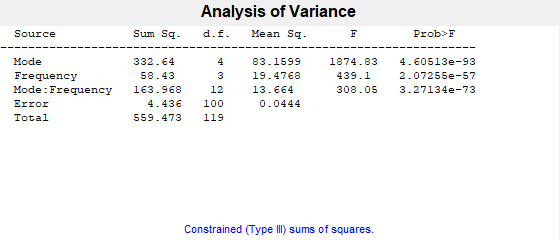

Power_W


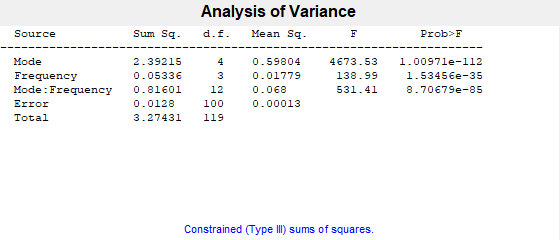

Energy_J


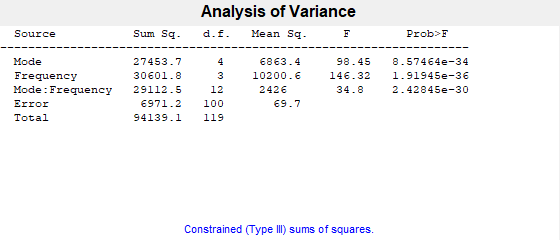

COT_J_kg_m


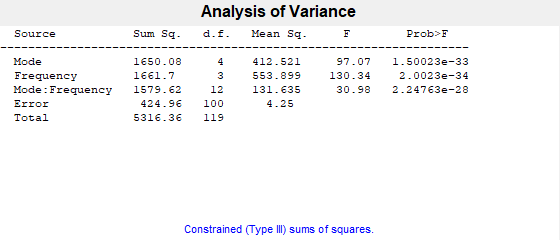

Results = readtable('swimming_results.csv');

%% ============================================
%% TWO-WAY ANOVA
%% ============================================

metrics = {'Speed_cm_s', ...
           'Power_W', ...
           'Energy_J', ...
           'COT_J_kg_m'};

for i = 1:length(metrics)

    metric = metrics{i};

    fprintf('\n====================================\n');
    fprintf('%s\n', metric);
    fprintf('====================================\n');

    y = Results.(metric);

    good = ~isnan(y);

    [p,tbl,stats] = anovan( ...
        y(good), ...
        {Results.Mode(good), ...
         Results.Frequency_Hz(good)}, ...
        'model','interaction', ...
        'varnames',{'Mode','Frequency'}, ...
        'display','on');

end

clear; clc; close all;

%% ============================================
%% LOAD RESULTS
%% ============================================

Results = readtable('swimming_results.csv');

%% ============================================
%% SETTINGS
%% ============================================

alpha = 0.05;

modeList = unique(Results.Mode, 'stable');
freqList = unique(Results.Frequency_Hz);

colors = lines(length(modeList));

lineWidth = 1.5;
markerSize = 6;

%% Figure size [cm]
plotW = 8.5;
plotH = 4.5;

%% ============================================
%% BONFERRONI CORRECTION
%% ============================================

nModes = length(modeList);

nComparisons = nchoosek(nModes,2);

alphaAdj = alpha / nComparisons

alphaAdj = 0.0050


fprintf('\n');
fprintf('========================================\n');

fprintf('Bonferroni corrected alpha = %.5f\n', ...
    alphaAdj);

Bonferroni corrected alpha = 0.00500


fprintf('========================================\n\n');

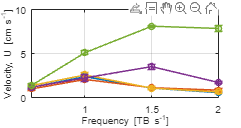

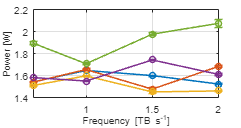

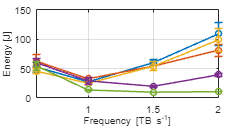

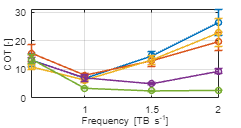


%% ============================================
%% METRICS
%% ============================================

metrics = {'Speed_cm_s', ...
           'Power_W', ...
           'Energy_J', ...
           'COT_J_kg_m'};

ylabels = {'Velocity, U [cm s^{-1}]', ...
           'Power [W]', ...
           'Energy [J]', ...
           'COT [-]'};

titles = {'Swimming Speed vs Frequency', ...
          'Power Consumption vs Frequency', ...
          'Energy Consumption vs Frequency', ...
          'Cost of Transport vs Frequency'};

fileNames = {'speed_vs_frequency.pdf', ...
             'power_vs_frequency.pdf', ...
             'energy_vs_frequency.pdf', ...
             'cot_vs_frequency.pdf'};

%% ============================================
%% PLOT ALL METRICS
%% ============================================

for metricIdx = 1:length(metrics)

    metric = metrics{metricIdx};

    fig = figure('Color','w');
    hold on

    %% ----------------------------------------
    %% LOOP MODES
    %% ----------------------------------------

    for m = 1:length(modeList)

        modeIdx = strcmp(Results.Mode, modeList{m});

        meanVals = nan(size(freqList));
        stdVals  = nan(size(freqList));
        nVals    = nan(size(freqList));

        %% ------------------------------------
        %% LOOP FREQUENCIES
        %% ------------------------------------

        for f = 1:length(freqList)

            idx = modeIdx & ...
                  Results.Frequency_Hz == freqList(f);

            vals = Results.(metric)(idx);

            vals = vals(~isnan(vals));

            meanVals(f) = mean(vals);
            stdVals(f)  = std(vals);
            nVals(f)    = length(vals);

        end

        %% ------------------------------------
        %% BONFERRONI CONFIDENCE INTERVALS
        %% ------------------------------------

        semVals = stdVals ./ sqrt(nVals);

        tcrit = tinv(1 - alphaAdj/2, nVals-1);

        ciVals = tcrit .* semVals;

        %% ------------------------------------
        %% ERRORBAR PLOT
        %% ------------------------------------

        errorbar(freqList, ...
                 meanVals, ...
                 stdVals, ...
                 '-o', ...
                 'Color', colors(m,:), ...
                 'LineWidth', lineWidth, ...
                 'MarkerSize', markerSize, ...
                 'CapSize', 8);

    end

    %% ----------------------------------------
    %% FORMATTING
    %% ----------------------------------------

    xlabel('Frequency [TB s^{-1}]','Interpreter','tex');
    ylabel(ylabels{metricIdx},'Interpreter','tex');
    xlim([0.6 2])

    grid on
    box on

    fontsize(10,'points');

    set(fig, ...
        'Units', 'centimeters', ...
        'Position', [2 2 plotW plotH]);

    set(fig, 'PaperUnits', 'centimeters');
    set(fig, 'PaperSize', [plotW plotH]);
    set(fig, 'PaperPosition', [0 0 plotW plotH]);
    set(fig, 'PaperPositionMode', 'manual');

    drawnow;

    %% Uncomment if desired
     print(fig, fileNames{metricIdx}, '-dpdf', '-vector');

end


%% ============================================
%% PAIRWISE STATISTICAL TESTS
%% ============================================

fprintf('\n');
fprintf('========================================\n');

fprintf('PAIRWISE BONFERRONI TESTS\n');

PAIRWISE BONFERRONI TESTS


fprintf('========================================\n');


%% Create statistics table
StatsTable = table();

for metricIdx = 1:length(metrics)

    metric = metrics{metricIdx};

    fprintf('\n');
    fprintf('========================================\n');
    fprintf('%s\n', metric);
    fprintf('========================================\n');

    %% ----------------------------------------
    %% LOOP FREQUENCIES
    %% ----------------------------------------

    for f = 1:length(freqList)

        freq = freqList(f);

        fprintf('\nFrequency = %.1f Hz\n', freq);

        %% ------------------------------------
        %% PAIRWISE MODE COMPARISONS
        %% ------------------------------------

        for m1 = 1:length(modeList)-1

            for m2 = m1+1:length(modeList)

                %% Condition 1
                idx1 = strcmp(Results.Mode, modeList{m1}) & ...
                       Results.Frequency_Hz == freq;

                vals1 = Results.(metric)(idx1);
                vals1 = vals1(~isnan(vals1));

                %% Condition 2
                idx2 = strcmp(Results.Mode, modeList{m2}) & ...
                       Results.Frequency_Hz == freq;

                vals2 = Results.(metric)(idx2);
                vals2 = vals2(~isnan(vals2));

                %% Skip insufficient data
                if length(vals1) < 2 || ...
                   length(vals2) < 2

                    continue;
                end

                %% Two-sample t-test
                [~, p] = ttest2(vals1, vals2);

                %% Significance
                if p < alphaAdj
                    significance = "Significant";
                else
                    significance = "Insignificant";
                end

                %% Print to command window
                fprintf('%s vs %s : p = %.5f --> %s\n', ...
                    modeList{m1}, ...
                    modeList{m2}, ...
                    p, ...
                    significance);

                %% Save row
                newRow = table( ...
                    string(metric), ...
                    freq, ...
                    string(modeList{m1}), ...
                    string(modeList{m2}), ...
                    p, ...
                    string(significance), ...
                    'VariableNames', ...
                    {'Metric', ...
                     'Frequency_Hz', ...
                     'Mode1', ...
                     'Mode2', ...
                     'p_value', ...
                     'Result'});

                StatsTable = [StatsTable; newRow];

            end
        end
    end
end

Speed_cm_s



Frequency = 0.6 Hz


anguilliform vs subcarangiform : p = 0.16441 --> Insignificant
anguilliform vs carangiform : p = 0.10919 --> Insignificant
anguilliform vs thunniform : p = 0.90790 --> Insignificant
anguilliform vs ostraciiform : p = 0.10725 --> Insignificant
subcarangiform vs carangiform : p = 0.00165 --> Significant
subcarangiform vs thunniform : p = 0.03874 --> Insignificant
subcarangiform vs ostraciiform : p = 0.00276 --> Significant
carangiform vs thunniform : p = 0.01748 --> Insignificant
carangiform vs ostraciiform : p = 0.83441 --> Insignificant
thunniform vs ostraciiform : p = 0.03065 --> Insignificant



Frequency = 1.0 Hz


anguilliform vs subcarangiform : p = 0.00065 --> Significant
anguilliform vs carangiform : p = 0.18726 --> Insignificant
anguilliform vs thunniform : p = 0.43220 --> Insignificant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.00553 --> Insignificant
subcarangiform vs thunniform : p = 0.32295 --> Insignificant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.14747 --> Insignificant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant



Frequency = 1.5 Hz


anguilliform vs subcarangiform : p = 0.57019 --> Insignificant
anguilliform vs carangiform : p = 0.96811 --> Insignificant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.59229 --> Insignificant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00000 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant



Frequency = 2.0 Hz


anguilliform vs subcarangiform : p = 0.00436 --> Significant
anguilliform vs carangiform : p = 0.35591 --> Insignificant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.03423 --> Insignificant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00000 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant


Power_W



Frequency = 0.6 Hz


anguilliform vs subcarangiform : p = 0.68986 --> Insignificant
anguilliform vs carangiform : p = 0.00000 --> Significant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.00000 --> Significant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00000 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant



Frequency = 1.0 Hz


anguilliform vs subcarangiform : p = 0.01283 --> Insignificant
anguilliform vs carangiform : p = 0.00000 --> Significant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.00000 --> Significant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00000 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant



Frequency = 1.5 Hz


anguilliform vs subcarangiform : p = 0.00000 --> Significant
anguilliform vs carangiform : p = 0.00000 --> Significant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.01331 --> Insignificant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00000 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant



Frequency = 2.0 Hz


anguilliform vs subcarangiform : p = 0.00000 --> Significant
anguilliform vs carangiform : p = 0.00000 --> Significant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.00000 --> Significant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00000 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant


Energy_J



Frequency = 0.6 Hz


anguilliform vs subcarangiform : p = 0.13711 --> Insignificant
anguilliform vs carangiform : p = 0.11009 --> Insignificant
anguilliform vs thunniform : p = 0.15579 --> Insignificant
anguilliform vs ostraciiform : p = 0.71392 --> Insignificant
subcarangiform vs carangiform : p = 0.00606 --> Insignificant
subcarangiform vs thunniform : p = 0.63892 --> Insignificant
subcarangiform vs ostraciiform : p = 0.18364 --> Insignificant
carangiform vs thunniform : p = 0.00079 --> Significant
carangiform vs ostraciiform : p = 0.02196 --> Insignificant
thunniform vs ostraciiform : p = 0.21360 --> Insignificant



Frequency = 1.0 Hz


anguilliform vs subcarangiform : p = 0.00165 --> Significant
anguilliform vs carangiform : p = 0.05986 --> Insignificant
anguilliform vs thunniform : p = 0.55130 --> Insignificant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.00067 --> Significant
subcarangiform vs thunniform : p = 0.22066 --> Insignificant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.16576 --> Insignificant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00012 --> Significant



Frequency = 1.5 Hz


anguilliform vs subcarangiform : p = 0.12984 --> Insignificant
anguilliform vs carangiform : p = 0.11872 --> Insignificant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.96981 --> Insignificant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00000 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant



Frequency = 2.0 Hz


anguilliform vs subcarangiform : p = 0.01033 --> Insignificant
anguilliform vs carangiform : p = 0.38335 --> Insignificant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.08562 --> Insignificant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00003 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant


COT_J_kg_m



Frequency = 0.6 Hz


anguilliform vs subcarangiform : p = 0.15245 --> Insignificant
anguilliform vs carangiform : p = 0.04740 --> Insignificant
anguilliform vs thunniform : p = 0.90320 --> Insignificant
anguilliform vs ostraciiform : p = 0.82708 --> Insignificant
subcarangiform vs carangiform : p = 0.00333 --> Significant
subcarangiform vs thunniform : p = 0.07528 --> Insignificant
subcarangiform vs ostraciiform : p = 0.14539 --> Insignificant
carangiform vs thunniform : p = 0.00356 --> Significant
carangiform vs ostraciiform : p = 0.00505 --> Insignificant
thunniform vs ostraciiform : p = 0.62152 --> Insignificant



Frequency = 1.0 Hz


anguilliform vs subcarangiform : p = 0.00074 --> Significant
anguilliform vs carangiform : p = 0.07075 --> Insignificant
anguilliform vs thunniform : p = 0.76903 --> Insignificant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.00076 --> Significant
subcarangiform vs thunniform : p = 0.10192 --> Insignificant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.19664 --> Insignificant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00002 --> Significant



Frequency = 1.5 Hz


anguilliform vs subcarangiform : p = 0.12845 --> Insignificant
anguilliform vs carangiform : p = 0.16011 --> Insignificant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.78289 --> Insignificant
subcarangiform vs thunniform : p = 0.00000 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00000 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant



Frequency = 2.0 Hz


anguilliform vs subcarangiform : p = 0.01396 --> Insignificant
anguilliform vs carangiform : p = 0.21514 --> Insignificant
anguilliform vs thunniform : p = 0.00000 --> Significant
anguilliform vs ostraciiform : p = 0.00000 --> Significant
subcarangiform vs carangiform : p = 0.22199 --> Insignificant
subcarangiform vs thunniform : p = 0.00002 --> Significant
subcarangiform vs ostraciiform : p = 0.00000 --> Significant
carangiform vs thunniform : p = 0.00006 --> Significant
carangiform vs ostraciiform : p = 0.00000 --> Significant
thunniform vs ostraciiform : p = 0.00000 --> Significant



%% ============================================
%% DISPLAY / SAVE TABLE
%% ============================================

disp(StatsTable)

       Metric       Frequency_Hz         Mode1               Mode2           p_value          Result     
    ____________    ____________    ________________    ________________    __________    _______________

    "Speed_cm_s"        0.6         "anguilliform"      "subcarangiform"       0.16441    "Insignificant"
    "Speed_cm_s"        0.6         "anguilliform"      "carangiform"          0.10919    "Insignificant"
    "Speed_cm_s"        0.6         "anguilliform"      "thunniform"            0.9079    "Insignificant"
    "Speed_cm_s"        0.6         "anguilliform"      "ostraciiform"         0.10725    "Insignificant"
    "Speed_cm_s"        0.6         "subcarangiform"    "carangiform"        0.0016518    "Significant"  
    "Speed_cm_s"        0.6         "subcarangiform" 


writetable(StatsTable, ...
    'pairwise_statistics.csv');

fprintf('\n');
fprintf('========================================\n');

fprintf('Statistics table saved:\n');

Statistics table saved:


fprintf('pairwise_statistics.csv\n');

pairwise_statistics.csv


fprintf('========================================\n');


%% ============================================
%% WITHIN-MODE FREQUENCY COMPARISONS
%% ============================================

nFreqs = length(freqList);

nComparisons = nchoosek(nFreqs,2);

alphaAdj = alpha / nComparisons

alphaAdj = 0.0083


fprintf('\n');
fprintf('========================================\n');

fprintf('WITHIN-MODE FREQUENCY COMPARISONS\n');

WITHIN-MODE FREQUENCY COMPARISONS


fprintf('========================================\n');


%% Create frequency statistics table
FreqStatsTable = table();

for metricIdx = 1:length(metrics)

    metric = metrics{metricIdx};

    fprintf('\n');
    fprintf('========================================\n');
    fprintf('%s\n', metric);
    fprintf('========================================\n');

    %% ----------------------------------------
    %% LOOP MODES
    %% ----------------------------------------

    for m = 1:length(modeList)

        currentMode = modeList{m};

        fprintf('\n');
        fprintf('Mode = %s\n', currentMode);

        %% ------------------------------------
        %% PAIRWISE FREQUENCY COMPARISONS
        %% ------------------------------------

        for f1 = 1:length(freqList)-1

            for f2 = f1+1:length(freqList)

                freq1 = freqList(f1);
                freq2 = freqList(f2);

                %% Data for frequency 1
                idx1 = strcmp(Results.Mode, currentMode) & ...
                       Results.Frequency_Hz == freq1;

                vals1 = Results.(metric)(idx1);

                vals1 = vals1(~isnan(vals1));

                %% Data for frequency 2
                idx2 = strcmp(Results.Mode, currentMode) & ...
                       Results.Frequency_Hz == freq2;

                vals2 = Results.(metric)(idx2);

                vals2 = vals2(~isnan(vals2));

                %% Skip insufficient data
                if length(vals1) < 2 || ...
                   length(vals2) < 2

                    continue;
                end

                %% Two-sample t-test
                [~, p] = ttest2(vals1, vals2);

                %% Significance
                if p < alphaAdj
                    significance = "Significant";
                else
                    significance = "Insignificant";
                end

                %% Print result
                fprintf('%.1f Hz vs %.1f Hz : p = %.5f --> %s\n', ...
                    freq1, ...
                    freq2, ...
                    p, ...
                    significance);

                %% Save to table
                newRow = table( ...
                    string(metric), ...
                    string(currentMode), ...
                    freq1, ...
                    freq2, ...
                    p, ...
                    string(significance), ...
                    'VariableNames', ...
                    {'Metric', ...
                     'Mode', ...
                     'Frequency1_Hz', ...
                     'Frequency2_Hz', ...
                     'p_value', ...
                     'Result'});

                FreqStatsTable = [FreqStatsTable; newRow];

            end
        end
    end
end

Speed_cm_s


Mode = anguilliform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.42214 --> Insignificant
0.6 Hz vs 2.0 Hz : p = 0.00028 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00004 --> Significant


Mode = subcarangiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.18936 --> Insignificant
0.6 Hz vs 2.0 Hz : p = 0.18744 --> Insignificant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.01312 --> Insignificant


Mode = carangiform


0.6 Hz vs 1.0 Hz : p = 0.00001 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00330 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00031 --> Significant


Mode = thunniform


0.6 Hz vs 1.0 Hz : p = 0.00008 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00003 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00008 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.01284 --> Insignificant
1.5 Hz vs 2.0 Hz : p = 0.00000 --> Significant


Mode = ostraciiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.15354 --> Insignificant


Power_W


Mode = anguilliform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00005 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00000 --> Significant


Mode = subcarangiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00006 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00000 --> Significant


Mode = carangiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.16526 --> Insignificant


Mode = thunniform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00019 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00000 --> Significant


Mode = ostraciiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00005 --> Significant


Energy_J


Mode = anguilliform


0.6 Hz vs 1.0 Hz : p = 0.00006 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.13306 --> Insignificant
0.6 Hz vs 2.0 Hz : p = 0.00007 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00011 --> Significant


Mode = subcarangiform


0.6 Hz vs 1.0 Hz : p = 0.00010 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.15059 --> Insignificant
0.6 Hz vs 2.0 Hz : p = 0.01435 --> Insignificant
1.0 Hz vs 1.5 Hz : p = 0.00006 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00036 --> Significant


Mode = carangiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.03280 --> Insignificant
0.6 Hz vs 2.0 Hz : p = 0.00008 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00042 --> Significant


Mode = thunniform


0.6 Hz vs 1.0 Hz : p = 0.00001 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00003 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00565 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00459 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00000 --> Significant


Mode = ostraciiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00080 --> Significant


COT_J_kg_m


Mode = anguilliform


0.6 Hz vs 1.0 Hz : p = 0.00007 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.26332 --> Insignificant
0.6 Hz vs 2.0 Hz : p = 0.00009 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00014 --> Significant


Mode = subcarangiform


0.6 Hz vs 1.0 Hz : p = 0.00008 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.08891 --> Insignificant
0.6 Hz vs 2.0 Hz : p = 0.04587 --> Insignificant
1.0 Hz vs 1.5 Hz : p = 0.00007 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00124 --> Significant


Mode = carangiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00812 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00016 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00001 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00109 --> Significant


Mode = thunniform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00007 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00224 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00359 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00000 --> Significant


Mode = ostraciiform


0.6 Hz vs 1.0 Hz : p = 0.00000 --> Significant
0.6 Hz vs 1.5 Hz : p = 0.00000 --> Significant
0.6 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.0 Hz vs 1.5 Hz : p = 0.00000 --> Significant
1.0 Hz vs 2.0 Hz : p = 0.00000 --> Significant
1.5 Hz vs 2.0 Hz : p = 0.00060 --> Significant



%% ============================================
%% DISPLAY / SAVE TABLE
%% ============================================

disp(FreqStatsTable)

       Metric             Mode          Frequency1_Hz    Frequency2_Hz     p_value          Result     
    ____________    ________________    _____________    _____________    __________    _______________

    "Speed_cm_s"    "anguilliform"           0.6                1         4.7543e-07    "Significant"  
    "Speed_cm_s"    "anguilliform"           0.6              1.5            0.42214    "Insignificant"
    "Speed_cm_s"    "anguilliform"           0.6                2         0.00027877    "Significant"  
    "Speed_cm_s"    "anguilliform"             1              1.5          2.159e-09    "Significant"  
    "Speed_cm_s"    "anguilliform"             1                2         2.2977e-11    "Significant"  
    "Speed_cm_s"    "anguilliform"           1.5                2  


writetable(FreqStatsTable, ...
    'within_mode_frequency_statistics.csv');

fprintf('\n');
fprintf('========================================\n');

fprintf('Frequency comparison table saved:\n');

Frequency comparison table saved:


fprintf('within_mode_frequency_statistics.csv\n');

within_mode_frequency_statistics.csv


fprintf('========================================\n');

Results = readtable('swimming_results.csv');

Re_vals = Results.Reynolds_number;
St_vals = Results.Strouhal_number;

Re_vals = Re_vals(~isnan(Re_vals));
St_vals = St_vals(~isnan(St_vals));

fprintf('\nDimensionless operating range:\n');


Dimensionless operating range:



fprintf('Re = %.0f ± %.0f, range %.0f–%.0f\n', ...
    mean(Re_vals), std(Re_vals), min(Re_vals), max(Re_vals));

Re = 12134 ± 11066, range 2450–42663



fprintf('St = %.2f ± %.2f, range %.2f–%.2f\n', ...
    mean(St_vals), std(St_vals), min(St_vals), max(St_vals));

St = 4.43 ± 2.15, range 1.38–10.24


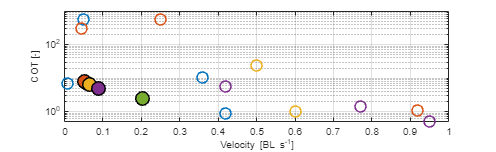

clear; clc; close all;

% Mode IDs:
% 1 = Anguilliform
% 2 = Subcarangiform
% 3 = Carangiform
% 4 = Thunniform
% 5 = Ostraciiform

names = {
    'OmniFish'
    'OmniFish'
    'OmniFish'
    'OmniFish'
    'OmniFish'

    'EELWORM [13]'
    'Pneumatic Eel Robot [14]'
    'FEDEA Biomorph [15]'
    'SoFi [16]'
    'SMA Subcarangiform Robot [17]'
    'Tunabot [21]'
    'Tunabot Flex [22]'
    'OpenFish [24]'
    'MARCO [26]'

    'DEA Robotic Fish [27]'
    'DEA Robotic Fish [27]'
    'DEA Robotic Fish [27]'
    'DEA Robotic Fish [27]'

    'Tensegrity Robotic Fish [28]'
    'Tensegrity Robotic Fish [28]'
    'Tensegrity Robotic Fish [28]'
    'Tensegrity Robotic Fish [28]'

    'Pangasius Fish Robot [20]'

    'DEA Subcarangiform Robot [18]'

    'DEA Carangiform Robot [19]'
};

mode = [
    1
    2
    3
    4
    5

    1
    1
    1
    3
    2
    4
    4
    4
    5

    1   % S-type ~ Anguilliform
    2   % C-type 1 ~ Subcarangiform
    3   % C-type 2 ~ Carangiform
    4   % C-type 3 ~ Thunniform

    1   % 0000 ~ Anguilliform
    2   % 1000 ~ Subcarangiform
    3   % 1100 ~ Carangiform
    4   % 1110 ~ Thunniform

    2

    2

    3
];

U_cm_s = [
    2.40
    2.09
    2.60
    3.55
    8.14

    3/60/400
    19
    0.19
    23.5
    2.45
    0.42*25.5
    0.95*25.5
    31.0
    4.11

    1.4
    1.05
    2.5
    2.0

    0.42*48
    0.45*48
    0.60*48
    0.77*48

    0.001

    3.72

    2.038
];

U_BL_s = [
    2.40/40
    2.09/40
    2.60/40
    3.55/40
    8.14/40

    3/60
    0.36
    0.009
    0.50
    24.5/250
    0.42
    0.95
    31/38.6
    4.11/15

    0.088
    0.066
    0.156
    0.125

    0.42
    0.92
    0.60
    0.77

    0.045

    0.25

    20.38/170
];

COT = [
    6.86
    7.94
    6.23
    4.94
    2.42

    48.84/(0.35*9.8*25*10^-3)
    10.72
    (20*10^-3)/(6*25.1*10^-3*9.8*0.19*10^-2)
    (35*3600)/(1.6*9.8*329)
    NaN
    5.6
    0.51
    NaN
    NaN

    NaN
    NaN
    NaN
    NaN

    0.88
    1.05
    1.02
    1.42

    315

    0.92/(9.8*4.4*10^-3*0.0372)

    NaN
];

colors = lines(5);

plotW = 19.5;
plotH = 6;

%% Identify OmniFish entries

isOmni = startsWith(names,'Omni');

%% Plot 1: Speed–efficiency tradeoff
% Only robots with BOTH speed and COT

valid = ~isnan(U_BL_s) & ~isnan(COT);

fig = figure('Color','w');

hold on;
box on;
grid on;

for i = find(valid)'

    if isOmni(i)

        % Current work = highlighted

        scatter( ...
            U_BL_s(i), ...
            COT(i), ...
            180, ...
            colors(mode(i),:), ...
            'filled', ...
            'MarkerEdgeColor','k', ...
            'LineWidth',1.5);

    else

        % Literature = hollow

        scatter( ...
            U_BL_s(i), ...
            COT(i), ...
            120, ...
            colors(mode(i),:), ...
            'o', ...
            'LineWidth',1.5);

    end

    % text( ...
    %     U_BL_s(i)+0.01, ...
    %     COT(i), ...
    %     names{i}, ...
    %     'FontSize',8, ...
    %     'Interpreter','none');

end

set(gca,'YScale','log')

ylim([0 1000])

xlabel('Velocity [BL s^{-1}]');

ylabel('COT [-]');

fontsize(10,'points');

set(fig, ...
    'Units', 'centimeters', ...
    'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

%% Uncomment if desired
print(fig, 'speed-v-efficiency', '-dpdf', '-vector');

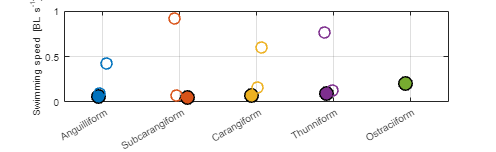


%% Plot 2: multimodal comparison only

fig = figure('Color','w');

hold on;
box on;
grid on;

rng(1)

isOmni = startsWith(names,'Omni');
isBionic = contains(names,'DEA Robotic Fish [27]');
isReconf = contains(names,'Tensegrity');

keep = (isOmni | isBionic | isReconf) ...
    & ~isnan(U_BL_s);

for i = find(keep)'

    xx = mode(i) + 0.08*randn;

    if isOmni(i)

        % Current work highlighted

        scatter( ...
            xx,...
            U_BL_s(i),...
            180,...
            colors(mode(i),:),...
            'filled',...
            'MarkerEdgeColor','k',...
            'LineWidth',1.5);

    else

        scatter( ...
            xx,...
            U_BL_s(i),...
            120,...
            colors(mode(i),:),...
            'o',...
            'LineWidth',1.5);

    end

    % text( ...
    %     xx+0.03,...
    %     U_BL_s(i),...
    %     names{i},...
    %     'FontSize',8,...
    %     'Interpreter','none');

end

xlim([0.5 5.5])

xticks(1:5)

xticklabels({ ...
    'Anguilliform',...
    'Subcarangiform',...
    'Carangiform',...
    'Thunniform',...
    'Ostraciiform'});

ylabel('Swimming speed [BL s^{-1}]');

fontsize(10,'points');

set(fig, ...
    'Units', 'centimeters', ...
    'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

%% Uncomment if desired
print(fig, 'speed-pr-mode', '-dpdf', '-vector');



T = table( ...
    names, ...
    mode, ...
    U_cm_s, ...
    U_BL_s, ...
    COT);

disp(T);

                  names                  mode     U_cm_s     U_BL_s      COT  
    _________________________________    ____    ________    _______    ______

    {'OmniFish'                     }     1           2.4       0.06      6.86
    {'OmniFish'                     }     2          2.09    0.05225      7.94
    {'OmniFish'                     }     3           2.6      0.065      6.23
    {'OmniFish'                     }     4          3.55    0.08875      4.94
    {'OmniFish'                     }     5          8.14     0.2035      2.42
    {'EELWORM [13]'                 }     1      0.000125       0.05    569.56
    {'Pneumatic Eel Robot [14]'     }     1            19       0.36     10.72
    {'FEDEA Biomorph [15]'          }     1          0.19      0.009    7.1322
    {'SoFi [16]'                    }  

function mask_out = fillShortGaps(mask_in, max_gap_pts)

    mask_out = mask_in(:);

    d = diff([false; mask_out; false]);

    start_idx = find(d == 1);
    end_idx   = find(d == -1) - 1;

    for i = 1:length(start_idx)-1

        gap_start = end_idx(i) + 1;
        gap_end   = start_idx(i+1) - 1;

        gap_len = gap_end - gap_start + 1;

        if gap_len <= max_gap_pts
            mask_out(gap_start:gap_end) = true;
        end
    end
end

function mask_out = removeShortBursts(mask_in, min_burst_pts)

    mask_out = mask_in(:);

    d = diff([false; mask_out; false]);

    start_idx = find(d == 1);
    end_idx   = find(d == -1) - 1;

    for i = 1:length(start_idx)

        burst_len = ...
            end_idx(i) - start_idx(i) + 1;

        if burst_len < min_burst_pts

            mask_out(start_idx(i):end_idx(i)) = false;

        end
    end
end